# **TCLab Projeto**

**Grupo**

- Luis Miguel Pereira Silva - 96534

- Pedro Miguel Oliveira Carvalho - 100507

- Rui Miguel Pereira Alves - 101428

**Professor: **Vinicius Corrêa Alves Silva

### Parametros do sistema


$$\begin{array}{l}
m=0\ldotp 004\;\textrm{kg}\;\left(\textrm{Massa}\right)\\
A=0\ldotp 0012m^{2\;} \left(\textrm{Área}\right)\\
\textrm{Cp}=500\;J/\textrm{kg}\;\textrm{ºC}\;\left(\textrm{Capacidade}\;\textrm{ca}\textrm{lorifica}\right)\\
\theta_{\textrm{Ambiente}} =22\;\textrm{ºC}\;\left(\textrm{Temperatura}\;\textrm{am}\textrm{biente}\right)\\
U=10\;W/m^2 \;\textrm{ºC}\;\left(\textrm{Coeficiente}\;\textrm{de}\;\textrm{co}\textrm{nvecção}\;\textrm{na}\textrm{tural}\right)\\
\alpha =0\ldotp 01\;W\;\left(\textrm{Relação}\;\textrm{entre}\;o\;\textrm{elemento}\;\textrm{de}\;\textrm{aquecimento}\;e\;a\;\textrm{potência}\;\textrm{de}\;\textrm{saída}\right)\\
q=50\;\left(\textrm{Elemento}\;\textrm{de}\;\textrm{aquecimento}\right)
\end{array}$$


%Parametros do sistema
m = 0.004;
A = 0.0012;
Cp = 500;
Ta = 22;
U = 10;
alfa = 0.01;
q = 50;

### 1.1 Usando a equação de balanço de energia (entra = sai + acumula) obtenha o modelo matemático do sistema (considere só a transferência de calor por convecção).


$$\begin{array}{l}
\textrm{entra}=\textrm{sai}+\textrm{acumula}\iff \\
\iff q\left(t\right)\alpha =q_{\textrm{Transistor}\to \textrm{Ambiente}} \left(t\right)+q_{\textrm{acumulado}} \left(t\right)\iff \\
\iff q\left(t\right)\alpha =\textrm{UA}\left({\theta \left(t\right)-\theta }_{\textrm{Ambiente}} \right)+m{\mathrm{C}}_p \frac{\mathrm{d}\theta \left(t\right)}{\mathrm{d}t}
\end{array}$$


### **1.2 **Encontre a função que descreve a evolução temporal da temperatura, i.e., encontre a solução analítica da equação diferencial. Nota: use as transformadas de Laplace.


$$\begin{array}{l}
q\left(t\right)\alpha =\textrm{UA}\left({\theta \left(t\right)-\theta }_{\textrm{Ambiente}} \right)+m{\mathrm{C}}_p \frac{\mathrm{d}\theta \left(t\right)}{\mathrm{d}t}\iff \\
\iff q\left(t\right)\alpha =\textrm{UA}\Delta \theta \left(t\right)+m{\mathrm{C}}_p \frac{\mathrm{d}\Delta \theta \left(t\right)}{\mathrm{d}t}\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \\
Q\left(s\right)\alpha =\left(\textrm{UA}+m{\mathrm{C}}_p s\right)\Delta \Theta \left(s\right)+m{\mathrm{C}}_p \Delta \theta \left(0\right)\iff \\
\iff \Delta \Theta \left(s\right)=\frac{\alpha }{\textrm{UA}+m{\mathrm{C}}_p s}Q\left(s\right)
\end{array}$$


Considerando que temos um degrau unitário á entrada, $q\left(t\right)=u\left(t\right)q\longrightarrow Q\left(s\right)=\frac{q}{s}$:


$$\Delta \Theta \left(s\right)=\frac{\alpha }{m{\mathrm{C}}_p \left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }+s\right)}\times \frac{q}{s}$$



$$A_1 =\lim_{S\to -\frac{\textrm{UA}}{m{\mathrm{C}}_p }} \frac{\alpha q}{m{\mathrm{C}}_p \left(-\frac{\textrm{UA}}{m{\mathrm{C}}_p }\right)}=-\frac{q\alpha }{\textrm{UA}}$$



$$A_2 =\lim_{S\to 0} \frac{\alpha q}{m{\mathrm{C}}_p \left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }\right)}=\frac{q\alpha }{\textrm{UA}}$$



$$\begin{array}{l}
\Rightarrow \Delta \Theta \left(s\right)=\frac{q\alpha }{\textrm{UA}}\left(-\frac{1}{\left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }+s\right)}+\frac{1}{s}\right)\iff \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\downarrow \\
\Delta \theta \left(t\right)=\frac{q\alpha }{\textrm{UA}}\left(1-e^{\frac{-\textrm{UA}}{m{\mathrm{C}}_p }t} \right)+\theta \left(0\right)\iff \\
\iff \Delta \theta \left(t\right)=\frac{q\alpha }{\textrm{UA}}\left(1-e^{\frac{-\textrm{UA}}{m{\mathrm{C}}_p }t} \right)+\theta_{\textrm{Ambiente}} 
\end{array}$$


Desta forma, a função da evolução temporal da temperatura com resposta ao degrau unitário tem o seguinte comportamento:

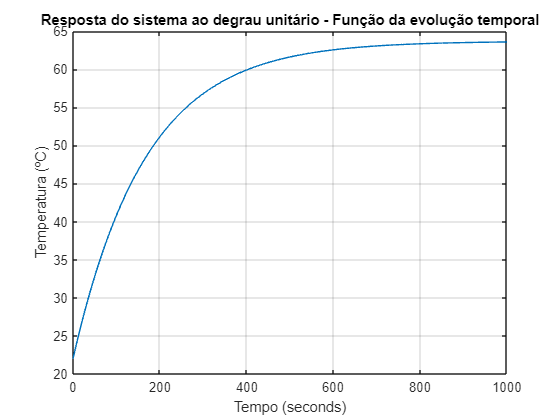

t=0:0.5:1000;
y = ((q*alfa)/(U*A))*(1-exp(-(U*A*t)/(m*Cp)))+Ta;
plot(t, y);
title('Resposta do sistema ao degrau unitário - Função da evolução temporal');
xlabel('Tempo (seconds)'), ylabel('Temperatura (ºC)');
grid on;
hold off;

### **1.3 **Represente o sistema recorrendo ao diagrama de blocos.

Primeiramente, para representar o sistema recorrendo ao diagrama de bloco é necessário o bloco do sinal de entrada (degrau unitário, cuja saida é o elemento de aquecimento, $q=50$ ligado ou $q=0$ desligado) ligando-o ao bloco da função transferência representada sob a forma de transformada de Laplace (obtida anteriormente). A saída deste bloco liga-se a um bloco somador, juntamente com a saída de uma constante com o valor da temperatura ambiente. Por fim, é necessário adicionar um "To Workspace" e um bloco do sinal de saída para conseguirmos obter e representar, respetivamente, o resultado.

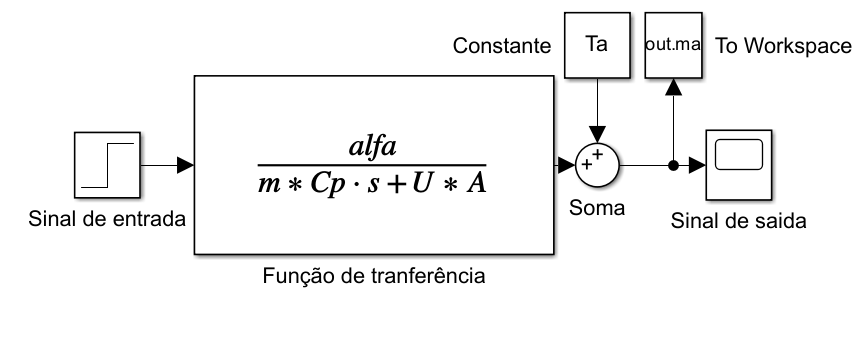

### **1.4 **Estude a resposta ao degrau unitário no MATLAB/SIMULINK (confirme os resultados que obteve) e classifique o sistema (justifique).

Usando o MATLAB/SIMULINK, a partir do sistema que se obteve em 1.2 ou apartir do diagrama de blocos representado em 1.3, obtem-se:

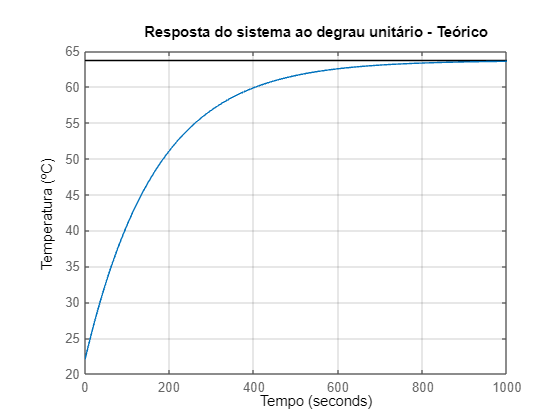

num = [0 alfa];
dem = [m*Cp U*A];
H = tf(num,dem);
step(q*H+Ta);
title('Resposta do sistema ao degrau unitário - Teórico');
xlabel('Tempo'), ylabel('Temperatura (ºC)');
grid on;
hold off;

Quanto à estabilidade do sistema, calculando os polos da função transferência:

    
$$\frac{\Delta \Theta \left(s\right)}{Q\left(s\right)}=\frac{\alpha }{m{\mathrm{C}}_p \left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }+s\right)}$$


Temos então:

    
$$\begin{array}{l}
m{\mathrm{C}}_p \left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }+s\right)=0\iff \\
\iff \left(\frac{\textrm{UA}}{m{\mathrm{C}}_p }+s\right)=0\iff \\
\iff s=-\;\frac{\textrm{UA}}{m{\mathrm{C}}_p }\;,\;m{\mathrm{C}}_p >0\wedge \textrm{UA}>0\Longrightarrow s<0
\end{array}$$


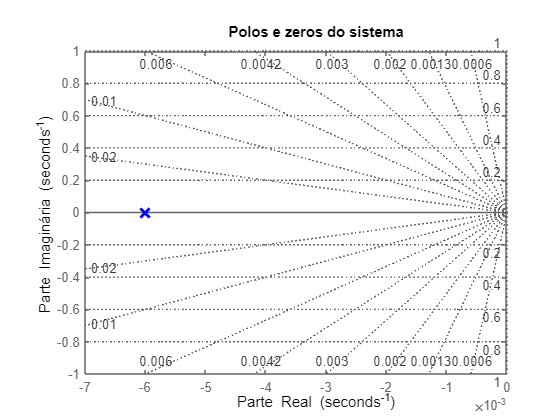

pzmap(H);
hold on;
title('Polos e zeros do sistema');
xlabel('Parte Real'), ylabel('Parte Imaginária');
xlim([-0.007, 0]);
plot(-0.006, 0, 'bx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;
grid on;

Assim, podemos concluir que o polo está no semiplano esquerdo, indicando que o sistema é estável. A mesma conclusão poderia ser retirada do gráfico obtido uma vez que este estabiliza a partir de um certo tempo, quando sujeito a um conjunto de condições iniciais.

Na prática, para avaliarmos a variação de temperatura do TCLab recorremos ao SIMULINK. Recorrendo a seguinte montagem,

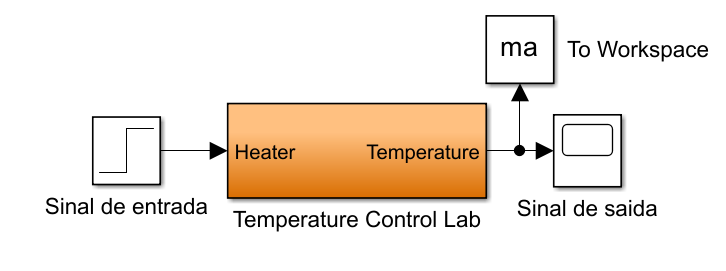

O diagrama de blocos é, por razões óbvias, muito semelhante ao obtido na questão 1.3, apenas retirando a função de transferência teórica e a constante (temperatura ambiente) adicionada e adicionando o bloco do TCLab (Temperature Control Lab).

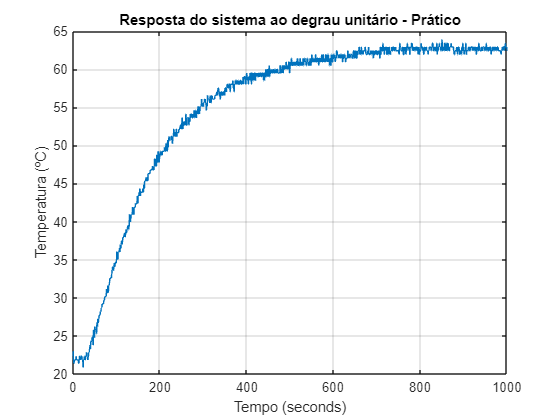

load('matlabmae.mat')
t = ma.Time;
y = ma.Data;
plot(t, y);
hold on;
title('Resposta do sistema ao degrau unitário - Prático');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
grid on;
hold off;

Observando os gráficos deste ponto, verifica-se que o gráfico obtido na prática é semelhante ao gráfico teórico. A principal divergência é o ruido, uma vez que é um sistema real, e está sujeito a perturbações do meio ambiente. Na pratica, a temperatura em regime premanente é inferior e há um atraso temporal inicial, isto pode ser derivado do sistema interno do TCLab (e um talvez seja a consequência do outro).

Na prática, verifica-se como anteriormente que o sistema é estavel.

### **1.5 **Qual é a constante de tempo do sistema.

Sabendo que:


$$\Delta \theta \left(t\right)=\frac{q\alpha }{\textrm{UA}}\left(1-e^{-\frac{\textrm{UA}}{m{\mathrm{C}}_p }t} \right)+\theta_{\textrm{Ambiente}}$$


Temos, 


$$\tau =$$

$$\frac{1}{\frac{\textrm{UA}}{m{\mathrm{C}}_p }}=\frac{{\textrm{mC}}_p }{\textrm{UA}}\approx 167\;\textrm{segundos}$$


A contante de tempo teórica é $\tau \approx 167\;\textrm{segundos}$, que corresponde ao tempo que demora a atingir 63.2% do valor final.

%Calculo auxiliar
tau=(m*Cp)/(U*A)

tau = 166.6667

É também possivel calcular a contante de tempo da resposta obtida experimentalmente, sabendo que $\tau$ é o tempo que demora a atingir 63.2% do valor em regime permanente. Assim, realiza-se uma média dos ultimos valores de temperatura e percorre-se a temperatura até 63.2% do obtido, o instante correspondente é a constante de tempo.

A contante de tempo prática é $\tau \approx 188\;\textrm{segundos}$.


$$1\tau \longrightarrow 63\ldotp 2%$$



$$2\tau \longrightarrow 86\ldotp 5%$$



$$3\tau \longrightarrow 95%$$



$$4\tau \longrightarrow 98\ldotp 2%$$


%Calculo auxiliar
lsty = y(end-100:end);
Tinfe = mean(lsty);
i=1;
while (Tinfe-Ta)*0.632>=(y(i)-Ta) 
    i=i+1;
end
taue=t(i)

taue = 188

### **1.6 **Qual é o erro em regime permanente do sistema. Considere a temperatura desejada de 50ºC?

Sabendo que em regime permanente a variação de temperatura é dada por, $\Delta \theta \left(\infty \right)$:


$$\begin{array}{l}
\Delta \theta \left(\infty \right)=\lim_{t\to \infty } \;\frac{q\alpha }{\textrm{UA}}\left(1-e^{-\frac{\textrm{UA}}{m{\mathrm{C}}_p }} \right)+\theta_{\textrm{Ambiente}} =\frac{q\alpha }{\textrm{UA}}\left(1-e^{-\infty } \right)+\theta_{\textrm{Ambiente}} \iff \\
\iff \Delta \theta \left(\infty \right)=\frac{q\alpha }{\textrm{UA}}+\theta_{\textrm{Ambiente}} =63,7\textrm{ºC}
\end{array}$$


%Calculo auxiliar
Tinf = ((q*alfa)/(U*A))+Ta

Tinf = 63.6667

Desta forma o erro em regime permanente,$\sigma$ é:


$$\sigma =\left|\Delta \theta \left(\infty \right)-\Delta \theta_{\textrm{desejada}} \right|=13,7\textrm{ºC}$$


%Calculo auxiliar
sigma = Tinf - 50

sigma = 13.6667

Na prática, o valor da temperatura em regime permanente corresponde a $\Delta \theta \left(\infty \right)=62,6\textrm{ºC}$.

Tinfe

Tinfe = 62.6371

Assim o erro em regime permanente,$\sigma$ é


$$\sigma =\left|\Delta \theta \left(\infty \right)-\Delta \theta_{\textrm{desejada}} \right|=12,6\textrm{ºC}$$


%Calculo auxiliar
sigmae = Tinfe - 50

sigmae = 12.6371

### **1.7** Simule o sistema com um controlador On/Off de ±2ºC recorrendo ao SIMULINK.

Um controlador On/Off altera o sistema entre dois estados, de forma a manter uma variável dentro de um intervalo desejado.

Neste caso, o controlador é responsável por ligar e desligar um atuador, o aquecedor, que liga quando o valor marcado como referência, $\theta_{\textrm{REF}}$ fica menor que o valor dado pela diferença entre a temperatura de referência e o seu limite de histerese, $\theta_{\textrm{REF}} -\theta_h \;$, e desliga quando $\theta_{\textrm{REF}}$ fica maior que a soma da temperatura de referência e o limite de histerese do controlador, $\theta_{\textrm{REF}} +\theta_h$. No nosso sitema a temperatura de referencia foi considerada $50\textrm{ºC}$,$\theta_{\textrm{REF}} =50\textrm{ºC}$ e a tolerância do controlador On/Off utilizado foi de $\pm 2\textrm{ºC}$.

A partir do seguinte sistema, onde foi acrescentado um "relay" que juntamente com uma realimentação negativa do sistema permite realizar o controlo On/Off. Basimamente subtrai-se o sinal de saida ao sinal de entrada para verificar se saiu ou não do limite de histerese e com o "relay", liga-se e desliga-se o aquecedor. O ganho adicional pode ser ajustado de forma a obter melhores resultados e o multiplexer premite obter e observar um conjunto de sinais juntamente com o sinal de saida.

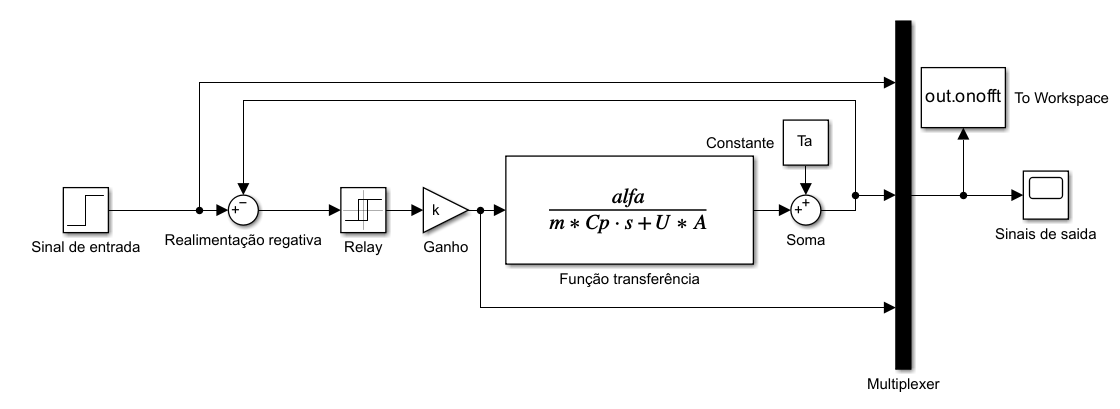

Desta forma, estudando para $k=50$ e $k=100$, temos para $k=50$: 

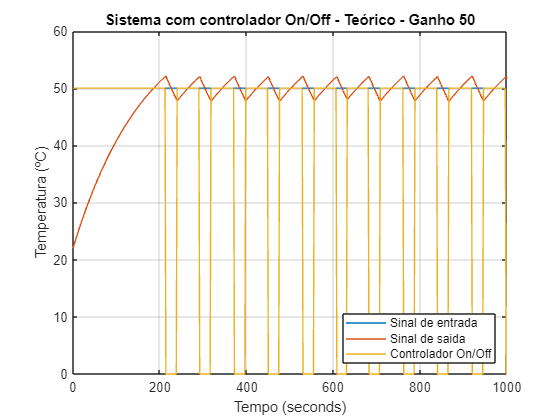

load('matlabonofft50.mat')
t = out.onofft.Time;
y = out.onofft.Data;
plot(t, y);
hold on;
title('Sistema com controlador On/Off - Teórico - Ganho 50');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Controlador On/Off','Location',"SouthEast")
grid on;
hold off;

Para $k=100$:

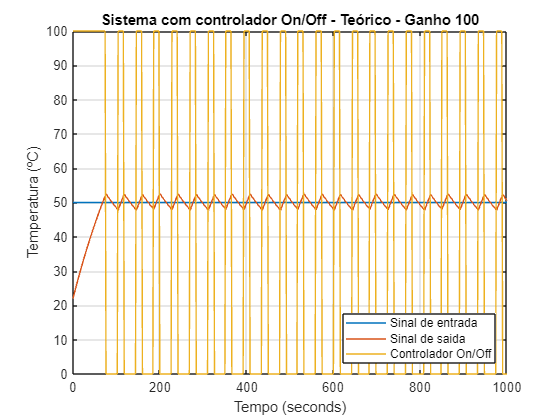

load('matlabonofft100.mat')
t = out.onofft.Time;
y = out.onofft.Data;
plot(t, y);
hold on;
title('Sistema com controlador On/Off - Teórico - Ganho 100');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Controlador On/Off','Location',"SouthEast")
grid on;
hold off;

Olhando para os gráficos acima, na teoria, podemos concluir que quanto maior o ganho melhor ajuste ao sinal de entrada, já que este oscila da mesma forma entre os valores de $\theta_{\textrm{REF}} -\theta_h =48\textrm{ºC}$ e $\theta_{\textrm{REF}} +\theta_h =52\textrm{ºC}$. Contudo, na pratica o resultado pode ser diferente. 

De forma a obter um sistema com um controlador On/Off de ±2ºC na prática, usa-se a seguinte montagem:

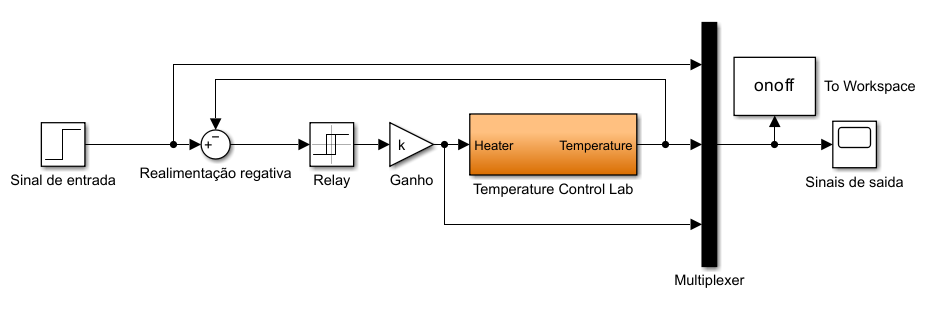

Novamente, apenas se troca a função tranferencia e a soma da temperatura ambiente pelo bloco da TClab (Temperature Control Lab), desta forma obtém se a seguinte resposta para $k=50$:

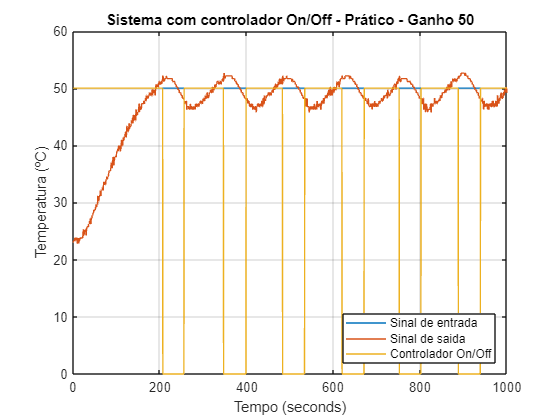

load('matlabonoff50.mat')
t = onoff.Time;
y = onoff.Data;
plot(t, y);
hold on;
title('Sistema com controlador On/Off - Prático - Ganho 50');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Controlador On/Off','Location',"SouthEast")
grid on;
hold off;

Para $k=100$:

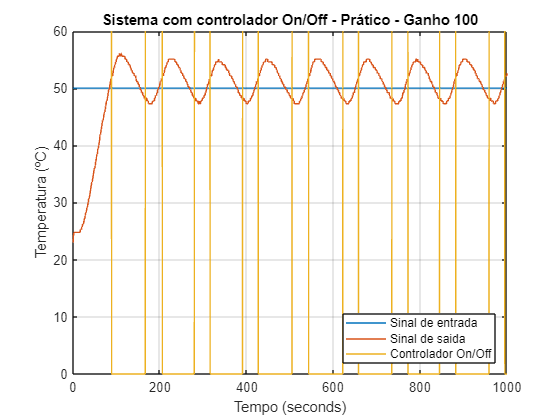

load('matlabonoff100.mat')
t = onoff.Time;
y = onoff.Data;
plot(t, y);
hold on;
title('Sistema com controlador On/Off - Prático - Ganho 100');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Controlador On/Off','Location',"SouthEast")
grid on;
ylim([0 60]);
hold off;

Na prática, com o aumento do ganho não se verifica um melhor ajuste. Com $k=50$, há um atraso na resposta quando se liga o aquecedor (compararando o sinal de saida com o controlador On/Off) já quando se desliga, esse atraso é despresável. Quando $k=100$, verifica-se novamente um atraso tanto quando se liga e também quando se desliga o aquecedor (aumentando assim a histerese).

### **1.8 **Sintonize um controlador PID para o sistema. Qual método usaria? Ajustar os parâmetros proporcional, integral e derivativo, para controlo do TCLab, analisando o efeito da variação de cada parâmetro no comportamento do sistema. Considere a temperatura de referência de 50ºC.

Segundo as regras de sintonização do PID (Regras de Ziegler-Nichols), o 1º método pode ser aplicado já que é estavel em forma de "S". Assim, para calcular os parâmetros proporcional, integral e derivativo, pode-se proceder de duas formas: 

- Tangente no ponto de inflexão; 

- Aproximações.

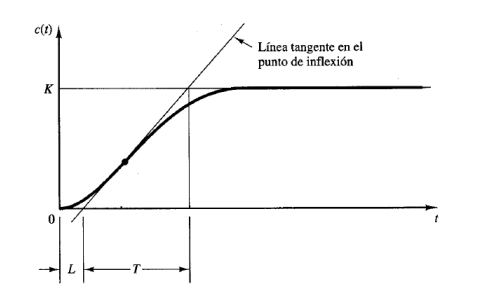

onde L correspode ao tempo de atraso e $\tau$ (L+T) a constante de tempo. Ziegler-Nichols propuseram fórmulas para determinar os parâmetros  Kp, Ti e Td, a partir dos valores de L e T para o 1º método:

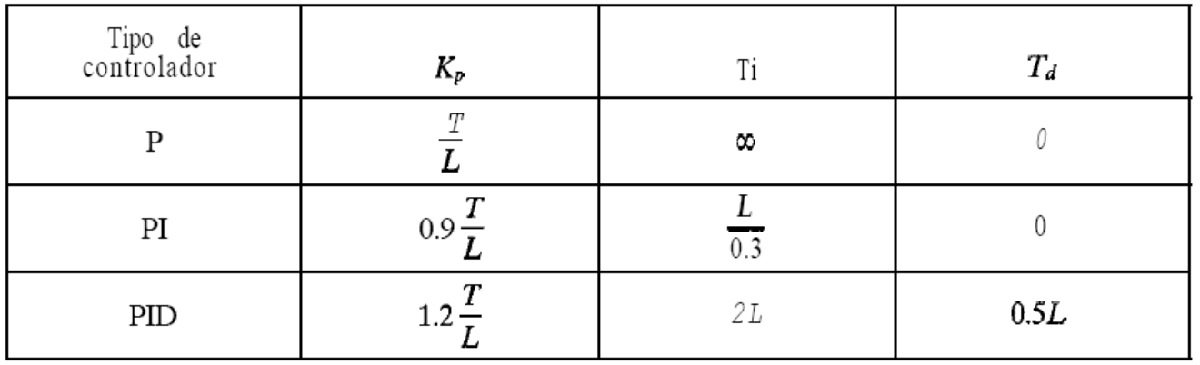 

 O ganho depende do tipo do controlador, mas a formula geral é $G_C \left(s\right)=K_p \left(1+\frac{1}{T_i s}+T_d s\right)$.

Na prática para descobrir os parametros para ajustar o PID, é necessário traçar uma tangente ao ponto de inflexão da resposta do sistema em malha aberta:

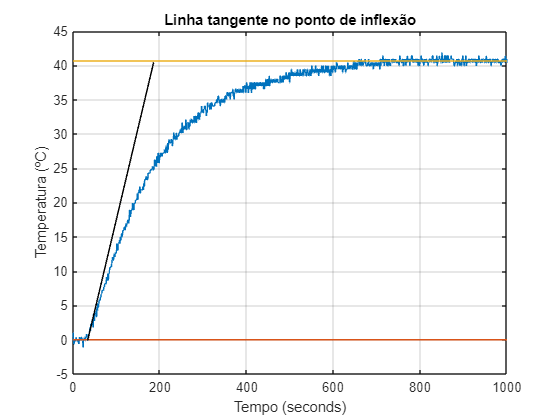

t = ma.Time;
y = ma.Data;
maxy = Tinfe-Ta;
plot(t,y-Ta);
hold on;
l1 = plot(t,0+t-t);
l2 = plot(t,maxy+t-t);
%datatip(l1,35,0);
%datatip(l2,taue,maxy);
annotation("line", [0.2744 0.1565], [0.8516 0.1892])
title('Linha tangente no ponto de inflexão');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
hold off;
grid on;

No gráfico acima, é traçado a olho a reta tangente. O $\tau$ tinha sido calculado no ponto 1.5 atravez de uma aproximação, o que ajuda a facilitar a obtenção do L e T. Desta forma,


$$\begin{array}{l}
L=35\;\textrm{segundos}\\
\tau \;=188\;\textrm{segundos}\\
T=\tau \;-L=153\;\textrm{segundos}
\end{array}$$


e por isso:


$$\begin{array}{l}
K_p \approx 5\ldotp 25\\
T_i \;=70\;\textrm{segundos}\\
T_d =15\ldotp 5\;\textrm{segundos}
\end{array}$$
 

Le = 35;
Te = taue-Le;
kp = 1.2*Te/Le;
Ti = (2*Le);
Td = 0.5*Le;

Recorrendo á seguinte montagem,

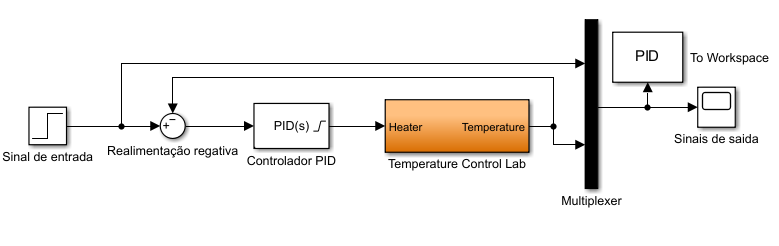

onde apenas se altera o controlo do On/Off com o "relay" e o ganho pelo controlador PID relativamente ao diagrama de blocos anterior. Agora ajustando os parametros do PID, é possivel estudar o comportamento relativamente aos parâmetros obtidos:

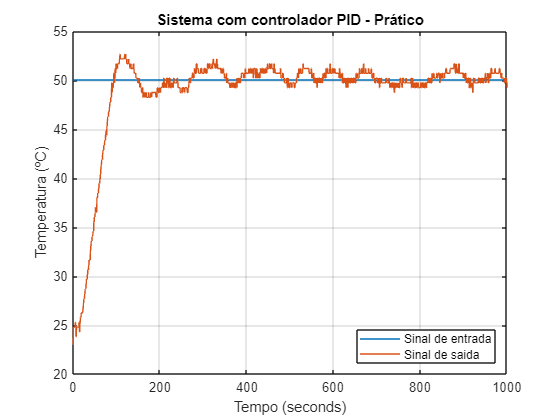

load('matlabPIDsu.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Prático');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

O gráfico apresentado mostra a resposta de um sistema estável (dado que não diverge) controlado por um controlador PID (Proporcional-Integral-Derivativo). No inicio a saída chega rapidamente a 50ºC, temperatura marcada como referência. Após o momento inicial, a temperatura oscila em torno desse valor. 

Agora, de modo a analisar o efeito da variação de cada parâmetro (proporcional, integral e derivativo) no comportamento do sistema, alteram-se os três parametros individualmente (aumentando e diminuindo 50% cada parâmetro).

#### Parâmetro proporcional

A ação proporcional é crucial para determinar a resposta imediata do sistema a erros atuais. Ela acelera a resposta do processo, reduzindo o tempo de subida e o erro máximo, mas ao custo de potencialmente aumentar o overshoot e o tempo de estabilização. Além disso, ela pode introduzir um off-set inversamente proporcional ao ganho.

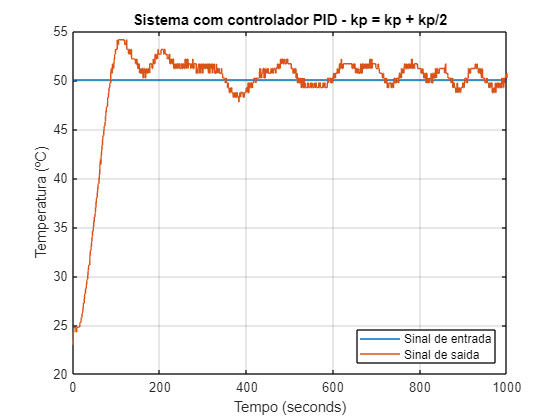

load('matlabPIDsukp+.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - kp = kp + kp/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

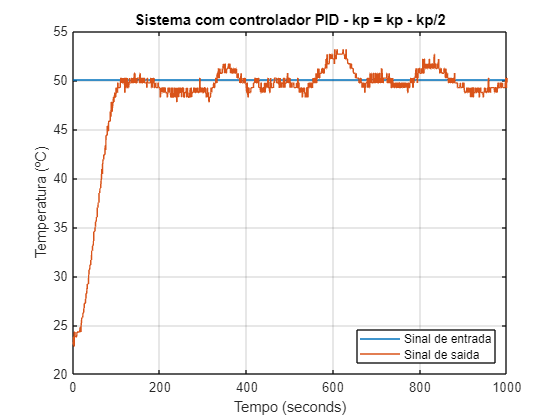

load('matlabPIDsukp-.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - kp = kp - kp/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Com o aumento do $K_p$, vemos que o tempo até atingir os 50ºC é mais pequeno. Observa-se também um aumento do overshoot, como seria de esperar. É ainda notório um aumento significativo da amplitude das oscilações à volta do setpoint, no entanto estas parecem diminuir em regime permanente.

#### Parâmetro i**ntegral**

A ação integral é essencial para eliminar o off-set e garantir que a saída do sistema alcança exatamente o setpoint desejado. No entanto, ao fazê-lo, ela pode introduzir efeitos indesejáveis, como aumento do overshoot, oscilações prolongadas e maior tempo de estabilização. Além disso, a ação integral pode resultar em respostas lentas e propensas a oscilações, e se não for adequadamente ajustada, pode levar à instabilidade do sistema.

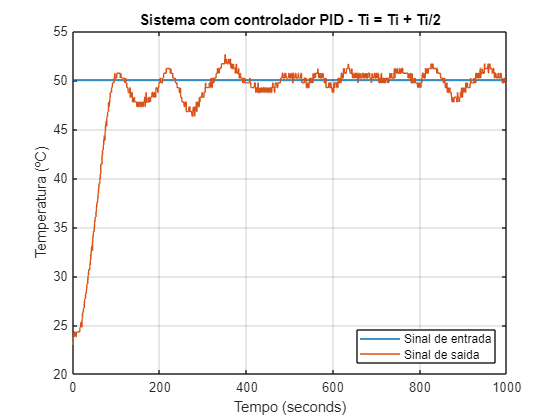

load('matlabPIDsuTi+.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Ti = Ti + Ti/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

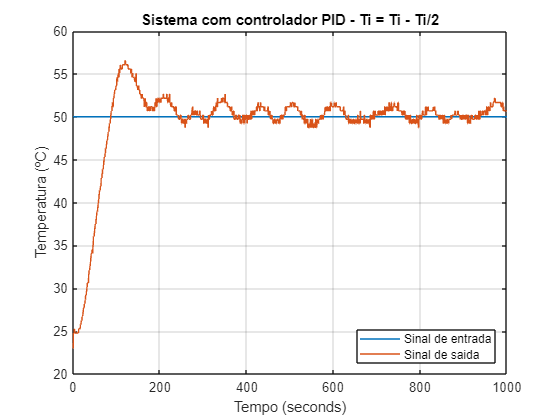

load('matlabPIDsuTi-.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Ti = Ti - Ti/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Com a diminuição do $T_i$ observa-se que o overshoot aumenta e o tempo de subida diminui, no entanto, as oscilações parecem ter a amplitude mais controlada e são claramente mais longas. 

#### Parâmetro derivativo

A ação derivativa é crucial para melhorar a resposta dinâmica do sistema, pela sua ação antecipatória. No entanto, pode introduzir efeitos indesejáveis, como amplificar o ruído no sinal. Além disso, a ação derivativa não corrige erros de estado estacionário por si só e deve ser usada juntamente com as ações proporcional e integral.

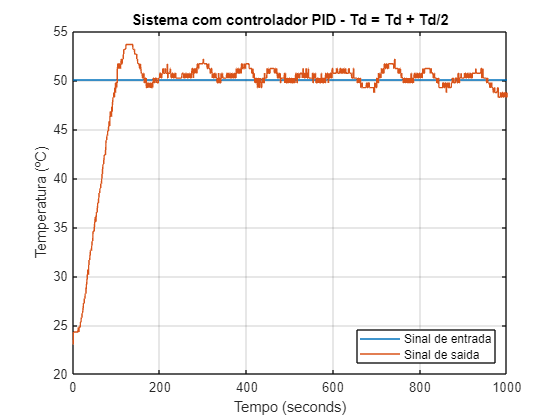

load('matlabPIDsuTd+.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Td = Td + Td/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

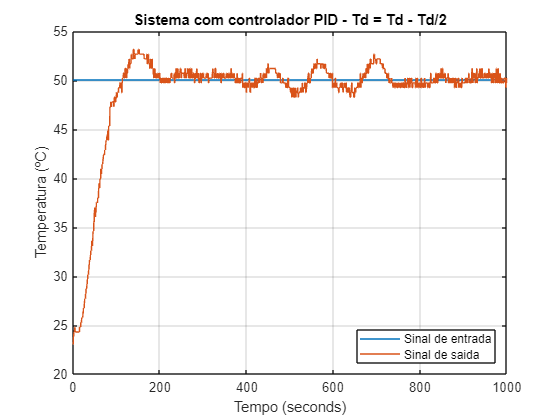

load('matlabPIDsuTd-.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Td = Td - Td/2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Com a diminuição do $T_d$ observa-se principalmente que as oscilações diminuiem.

De forma a realizar um estudo mais pormenorizado aplicamos um controlador P e PI, para saber como o nosso sistema responde com estes tipos de controlador.

#### **Controlador P e PI**

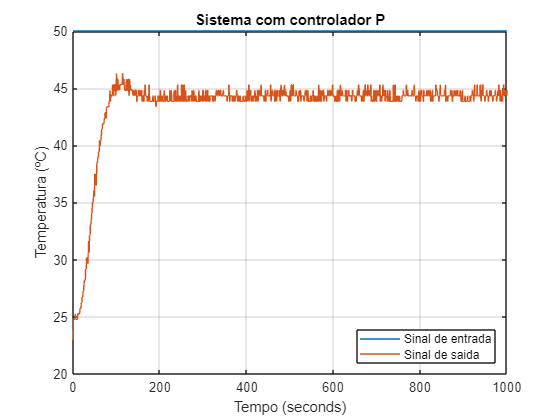

load('matlabPsu.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador P');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

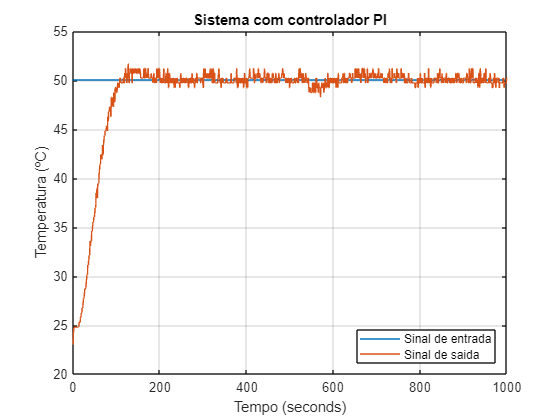

load('matlabPIsu.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PI');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Analisando os gráficos obtidos com o uso dos controladores PID, PI e P, conseguimos verificar que é com o controlador PI que obtemos os melhores resultados. 

Analisando o resultado para cada controlador concluimos que:

- **P** - Em comparação ao primeiro gráfico da resposta do sistema com controlador PID podemos afirmar que o controlador P não é suficiente para descrever o sinal de saída do sistema, estabilizando por volta dos 45ºC quando o esperado seria nos 50ºC. Isto deve-se à existência de um erro em estado estacionário, uma vez que o controlador P ajusta a saída proporcionalmente ao erro atual, mas não é capaz de eliminar completamente o erro em regime permanente;

- **PI** - Este controlador já permite ao sistema estabilizar próximo dos 50ºC, algo que não se verificou no controlador P. Isto deve-se à inclusão do termo integral, que é responsável por eliminar o erro em estado estacionário, acumulando o erro ao longo do tempo e ajustando a saída para corrigir esse erro acumulado. O pior desempenho do PID deve-se ao termo derivativo que cria instablidade na resposta, contudo, para entradas mais complexas o PID terá melhor resposta.

Na teoria, não podemos calcular os parâmetros L e T já que a resposta não tem a forma de um "S", contudo podem se variar os parâmetros proporcional, integral e derivativo.

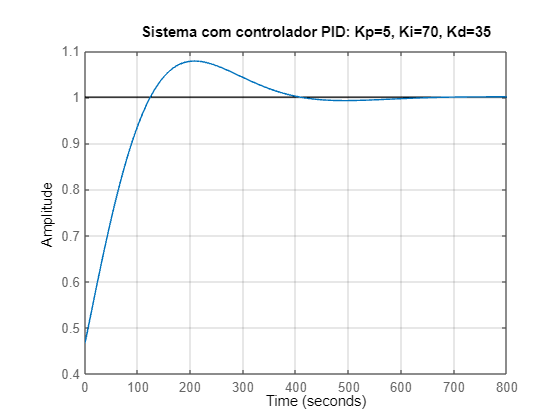

Kp =5;
Ki =70;
Kd =35;
C = pidstd(Kp, Ki, Kd);
sys = feedback(H*C, 1);
step(sys);
title(['Sistema com controlador PID: Kp=', num2str(Kp), ', Ki=', num2str(Ki), ', Kd=', num2str(Kd)]);
grid on;

e assim verificar tudo que foi afirmado acima. Ainda na teoria, embora não seja possivel calcular valores aproximados para os parâmetros, usamos os mesmos parâmetros da pratica para simular o sistema com controlador PID. Com o ajuste do sistema teórico com os parâmetros obtidos na pratica não os podemos comparar, contudo ao nivel de amplificação de ruido podemos tirar algumas conclusões já que não há ruido no sinal teórico.

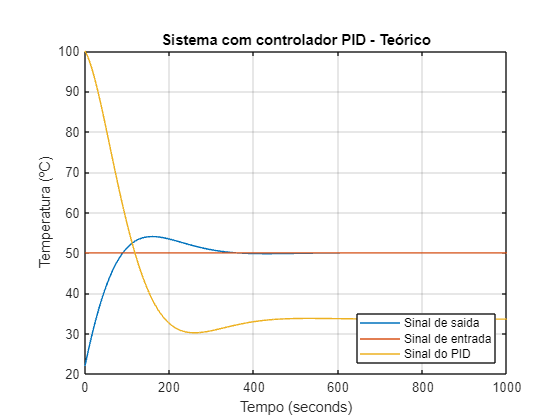

load('matlabPIDsuT.mat')
t = out.PID.Time;
y = out.PID.Data;
plot(t, y);
title('Sistema com controlador PID - Teórico');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de saida','Sinal de entrada','Sinal do PID','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

A principal diferença é a ausencia de oscilações após a establização, e possivelmente acontecerá o mesmo nos graficos teóricos apresentados na alinea 1.9 (apenas caso contrario será feito um comentário).

### **1.9** Simule o sistema com um controlador PID recorrendo ao SIMULINK/MATLAB com os seguintes sinais de entrada: (Nota: altere o tempo de simulação para 1000 segundos)

#### **a)** Após 10 segundos, o valor da temperatura de referência será de 40 °C. Após 5 minutos, o valor de referência passa a ser de 75 °C até ao final do teste.

A partir do seguinte diagrama de blocos,

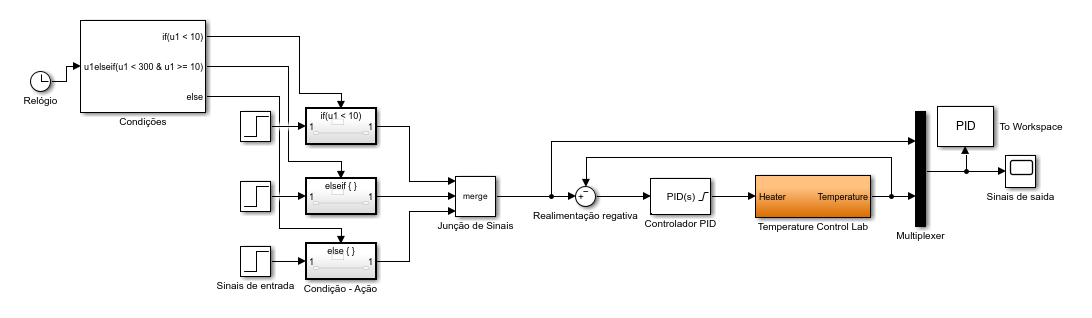

obtem-se a resposta do controlador PID ao sinal apresentado na alinea a. Neste diagrama é usado um conjunto de blocos para criar o sinal de entrada tais como "Clock" (Relógio), "if" (Conjunto de condições), "if action subsystem" (Realiza uma ação a partir de determinada condição) e o "merge" (Junta os sinais da entrada). A partir deste conjunto de blocos, considerando a questão e o gráfico apresentado nela cria-se a lógica para obter o sinal de entrada.

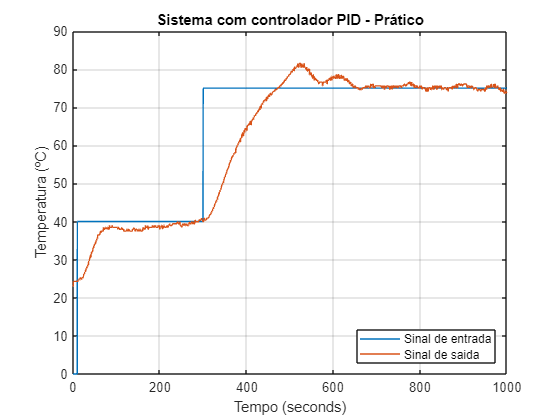

load('matlabPIDa.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Prático');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Acima, vemos que o sistema tem alguma dificuldade a se adaptar a mudanças repentinas de temperatura, no entanto, quando o faz é capaz de se manter ajustado à referencia.

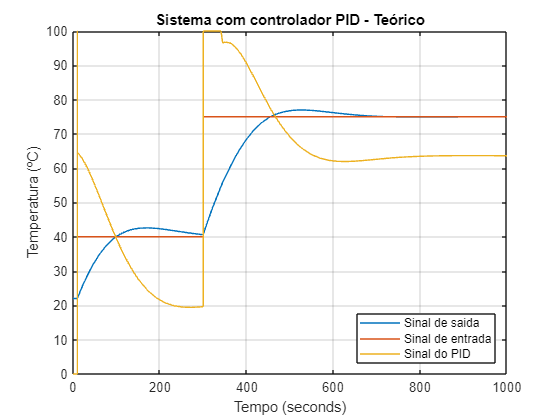

load('matlabPIDaT.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Teórico');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de saida','Sinal de entrada','Sinal do PID','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

#### **b)** Durante 3 minutos, o valor da temperatura de referência é 40 °C. Depois, a temperatura de referência deverá aumentar linearmente até 65 °C a uma taxa de 0.15ºC/s.

Novamente, alterando apenas a lógica do sinal de entrada com o seguinte diagrama de blocos,

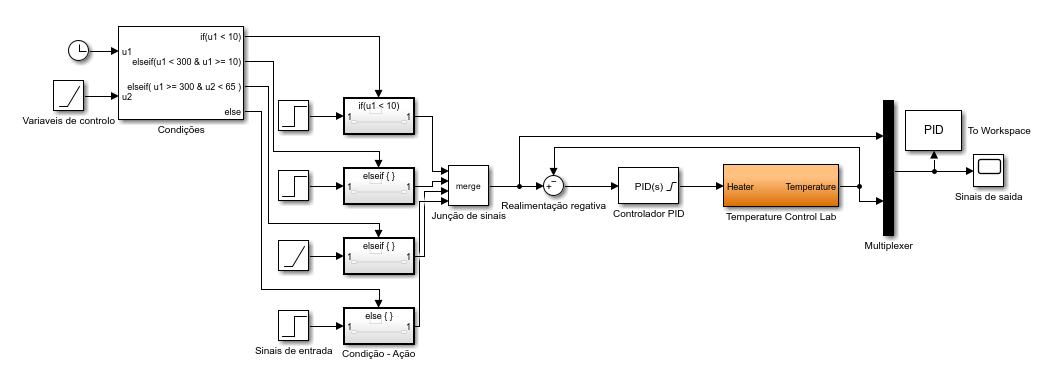

obtem-se a resposta do controlador PID ao sinal apresentado na alinea b.

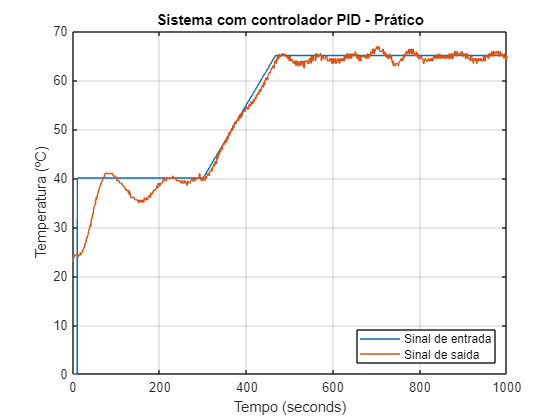

load('matlabPIDb.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Prático');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Aqui vemos a importância da ação derivativa no PID (apesar da instablidade em regime estacionário),ou seja ,quando há variações de temperatura mais lentas o sistema adpta-se muito bem. 

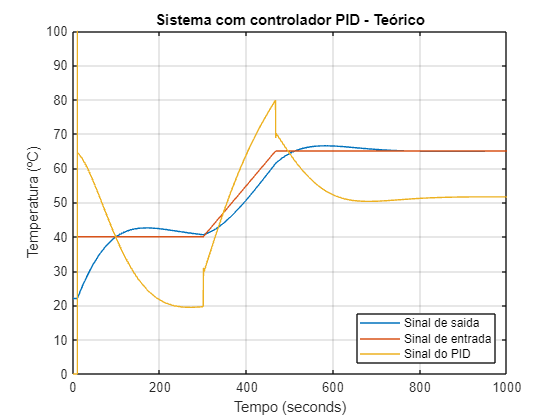

load('matlabPIDbT.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Teórico');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de saida','Sinal de entrada', 'Sinal do PID' ,'Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

#### **c)** Após 200 segundos, o valor da temperatura de referência passa de 40 °C para 55 °C. Após 200 segundos, o aquecedor 1 deve ser desligado. Quando valor da temperatura no sensor 1 atingir novamente os 40 °C, a temperatura deverá diminuir de forma linear (taxa de 0.05 °C/s) até aos 28 °C, mantendo-se neste patamar até ao final do teste.

Com diagrama de blocos abaixo,

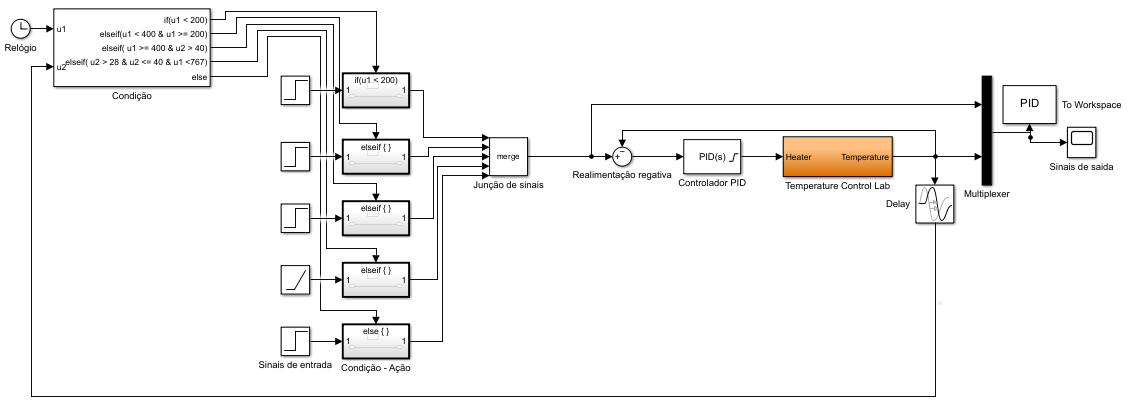

obteve-se a resposta á alinea c. Neste caso, de modo a obter o sinal de entrada foi necessário no conjunto de condições a variavel da temperatura de saida do sistema. Como na parte final do gráfico não tinhamos informação do tempo foi também necessário testar o sistema para saber aproximadamente quando é que os 40ºC eram atingidos e com isso saber o instante em que a temperatura establizava nos 28ºC. 

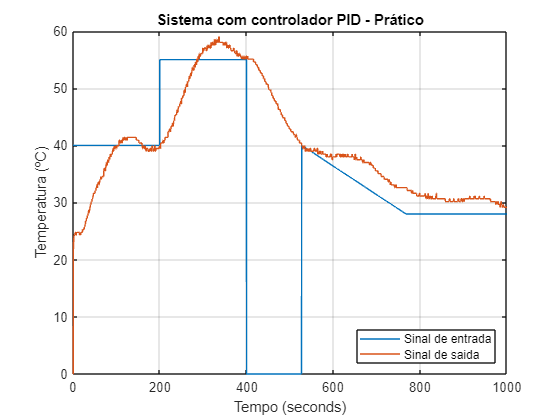

load('matlabPIDc.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Prático');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Neste caso, verificamos que nas diminuições de temperatura há um pior ajuste do controlador. No momento em que o aquecedor é desligado como o sistema é real a diminimuição de temperatura depende da dissipação da "case". Quando se atinge os 40ºC e se diminui lentamente a temperatura, a resposta não é ideal uma vez que se encontra acima do valor pretendido (sinal com overshoot), isto acontece provavelmente devido ao pico que inicia a rampa. 

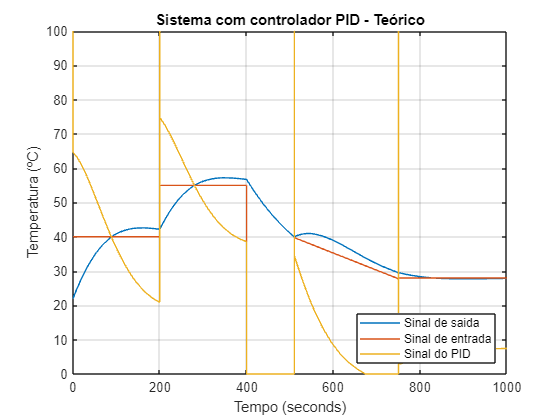

load('matlabPIDcT.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Teórico');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de saida','Sinal de entrada', 'Sinal do PID' ,'Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

#### **d) **Repetir a alínea a), adicionando uma perturbação ao processo: entre os 200 e 500 segundos, o aquecedor 2 passa de 0 a 100%, permanecendo desligado até ao final do teste.

Para a ultima pergunta usou-se o seguinte diagrama:

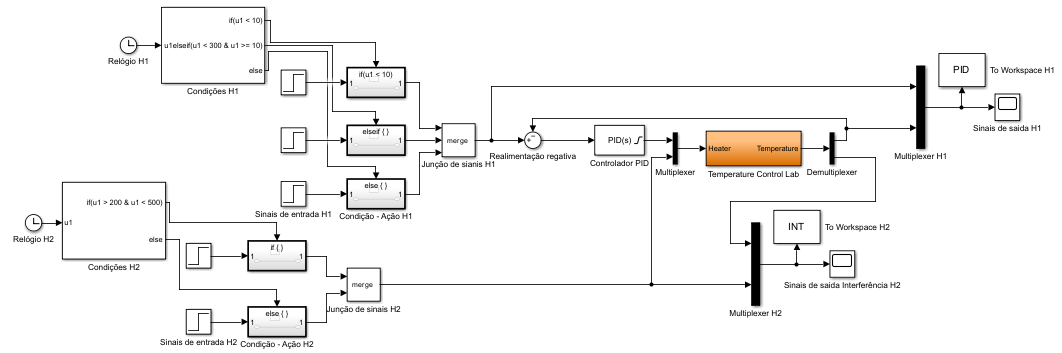

Neste caso são criados dois sinais de entrada (um para cada aquecedor), depois alterando a função do Temperature Control Lab para a arduino_tclab.m e o output da temperatura para um buffer de dois elementos, é possivel usar-se um multiplexer e um demultiplexer na entrada e saida do TCLab, respetivamente, de forma a enviar o sinal respetivo a cada aquecedor simultaneamente.

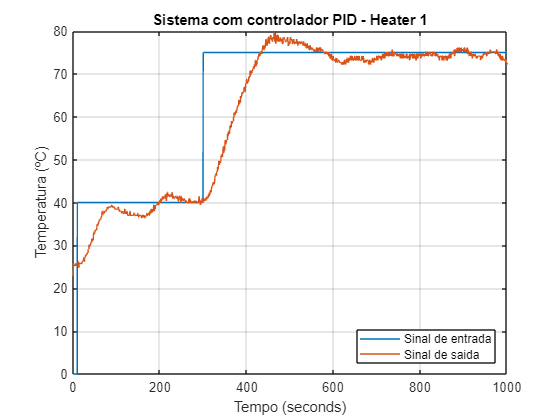

load('matlabPIDd.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID - Heater 1');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

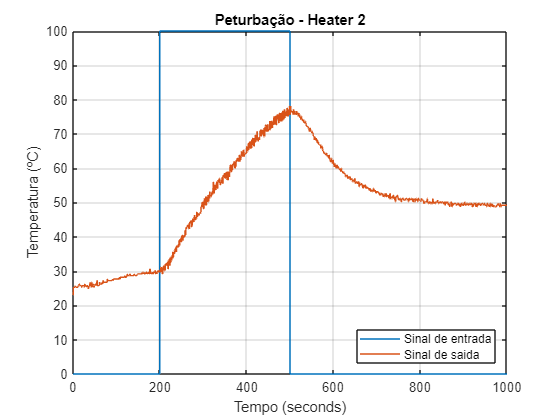

load('matlabPIDdI.mat')
t = INT.Time;
y = INT.Data;
plot(t, y);
title('Peturbação - Heater 2');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

Com o sistema PID projetado não se verificam diferenças significativas relativamente á alinea a no sinal de saida (apesar de aumentar o reuido de alta ferquencia). Contudo, no segundo aquecedor (responsavel pela peturbação) é possivel verificar um aquecimento até ao 30ºC inicialmente e no fim a temperatura establiza aos 50ºC, onde ambas resultam do calor do primeiro aquecedor.

### Extra

Como extra para este trabalho, decidimos analisar o comportamento do PID á corrente de ar. Desta forma, com o sinal de saida já estavel, varia-se o fluxo de ar.

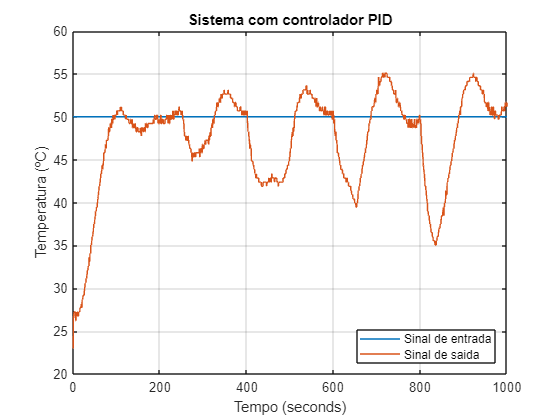

load('matlabEXTRA.mat')
t = PID.Time;
y = PID.Data;
plot(t, y);
title('Sistema com controlador PID');
xlabel('Tempo (seconds)'),ylabel('Temperatura (ºC)');
legend('Sinal de entrada','Sinal de saida','Location',"SouthEast")
grid on;
%xticks(0:100:1000);
%xticklabels({});
hold off;

As perturbações induzidas tiveram o seguinte comportamento:

- Aos 200 segundos iniciou-se a perturbação provocada pela corrente de ar quando se abriu as janelas.

- Aos 250 segundos com a ajuda de um livro a baixa intensidade agitou-se para aumentar a perturbação. 

- Aos 400 segundos aumentamos a intensidade de agitação, de modo a que fosse superior às anteriores.

- Aos 600 segundos com a ajuda de um secador na velocidade mais baixa, aumentou-se o fluxo de ar.

- Aos 800 segundos novamente com o secador mas na velocidade mais alta, aumentou-se ainda mais o fluxo de ar.

Observando o sinal de saida do sistema e as perturbações induzidas, podemos tirar algumas conclusões, primeiramente o fluxo de ar gerado pela abertura da janela não foi suficiente para afetar a resposta do sistema. Em segundo lugar, quanto maior for o fluxo do ar maior será a variação de temperatura. Por fim, quanto maior essa queda maior será o overshoot após retirar a fonte de refrigeração (é de notar ainda que o ultimo overshoot não ultrapassou o anterior talvez porque o sistema já estava a usar a potência maxima).